% Set random seed based on the current time to ensure different results for each run
rng('shuffle');  

% Parameters
format long

% Observed and estimated traffic flow data
observedQ = [300, 420, 480, 540, 600];  % Observed travel times (in seconds)
sigma = 30;                             % Standard deviation of observed data (in seconds)
lambda = 0.05;                          % Regularization parameter

% Additional Parameters for the Bangalore Metro Traffic Recovery
arrivalTimes = [300, 420, 240, 360, 480];  % in seconds
departureTimes = [0, 300, 420, 240, 360];  % in seconds
idealTimes = [240, 300, 360, 420, 480];    % in seconds
actualTimes = [300, 420, 480, 540, 600];   % in seconds
distances = [2000, 2000, 2500, 3000, 1500]; % in meters
speeds = [8.33, 8.33, 6.94, 5.56, 11.11];  % in m/s
gamma = 0.01;                              % Emission factor in kg CO₂ per meter
alpha = 0.05;                              % Fuel coefficient per distance
beta = 0.01;                               % Fuel coefficient per time
delta = 0.02;                              % Emission penalty factor
theta = 0.03;                              % Fuel consumption penalty factor

% Congestion-related parameters (Same as DE)
recklessDriving = [1, 0, 1, 0, 0];  % Binary array representing reckless driving instances
railroadDelays = [0, 1, 0, 0, 1];   % Binary array representing railroad delays
signalDelays = [1, 0, 1, 0, 0];     % Binary array representing signal delays
emissions = [0.5, 0.4, 0.3, 0.6, 0.7]; % Emissions for each trip
fuelConsumption = [0.1, 0.15, 0.2, 0.12, 0.1]; % Fuel consumption per trip

% DE parameters
numParticles = 5;                       % Number of traffic segments (dimensionality)
positionRange = [0, 1];                 % Position range for optimization
populationSize = 50;                    % Population size for DE
maxGenerations = 100;                   % Max generations for DE
tolerance = 1e-6;                       % Tolerance for minimal fitness change
maxStallGenerations = 10;               % Max generations to tolerate minimal change
stallCounter = 0;                       % Counter for stall generations

% Initialize population and fitness tracking
population = positionRange(1) + (positionRange(2) - positionRange(1)) * rand(populationSize, numParticles);
fitnessFunctionDE = @(Q) objectiveFunction(Q', observedQ, sigma, lambda, ...
    recklessDriving, railroadDelays, signalDelays, emissions, fuelConsumption, ...
    alpha, beta, gamma, delta, theta, actualTimes, speeds, distances);
bestFitnessValuesDE = zeros(1, maxGenerations);

% Start the timer
tic;

% DE Optimization Loop
disp('Running DE:');

Running DE:


for gen = 1:maxGenerations
    % Evaluate fitness of each individual in the population
    fitnessValues = arrayfun(@(idx) fitnessFunctionDE(population(idx, :)), 1:populationSize);
    
    % Store best fitness of the current generation
    [bestFitness, bestIndex] = min(fitnessValues);
    bestFitnessValuesDE(gen) = bestFitness;
    
    % Display current generation and best fitness
    disp(['Generation ', num2str(gen), ', Best Fitness: ', num2str(bestFitness)]);
    
    % Check for early stopping
    if gen > 1 && abs(bestFitnessValuesDE(gen) - bestFitnessValuesDE(gen-1)) < tolerance
        stallCounter = stallCounter + 1;
        if stallCounter >= maxStallGenerations
            disp(['Terminating early at generation ', num2str(gen), ' due to minimal change in fitness.']);
            break;
        end
    else
        stallCounter = 0;
    end
    
    % Mutation: Select three random individuals
    indices = randperm(populationSize, 3);
    x1 = population(indices(1), :);
    x2 = population(indices(2), :);
    x3 = population(indices(3), :);

    % Create a mutant vector
    mutant = x1 + 0.8 * (x2 - x3); % DE Mutation

    % Crossover: Blend mutant with current solution
    trial = population(1, :);
    for j = 1:numParticles
        if rand < 0.9 % Crossover probability
            trial(j) = mutant(j);
        end
    end

    % Ensure trial vector stays within bounds
    trial = min(max(trial, positionRange(1)), positionRange(2));

    % Selection: If trial is better than the current solution, replace it
    if fitnessFunctionDE(trial) < fitnessFunctionDE(population(1, :))
        population(1, :) = trial;
    end
end

Generation 1, Best Fitness: 0.27243
Generation 2, Best Fitness: 0.27243
Generation 3, Best Fitness: 0.27243
Generation 4, Best Fitness: 0.27243
Generation 5, Best Fitness: 0.27243
Generation 6, Best Fitness: 0.27243
Generation 7, Best Fitness: 0.27243
Generation 8, Best Fitness: 0.26201
Generation 9, Best Fitness: 0.26201
Generation 10, Best Fitness: 0.26201
Generation 11, Best Fitness: 0.26201
Generation 12, Best Fitness: 0.26201
Generation 13, Best Fitness: 0.26201
Generation 14, Best Fitness: 0.26201
Generation 15, Best Fitness: 0.26201
Generation 16, Best Fitness: 0.26201
Generation 17, Best Fitness: 0.26201
Generation 18, Best Fitness: 0.26201


Terminating early at generation 18 due to minimal change in fitness.



% Stop the timer and display runtime
totalTimeDE = toc;
disp(['Total Runtime: ', num2str(totalTimeDE), ' seconds']);

Total Runtime: 0.024381 seconds


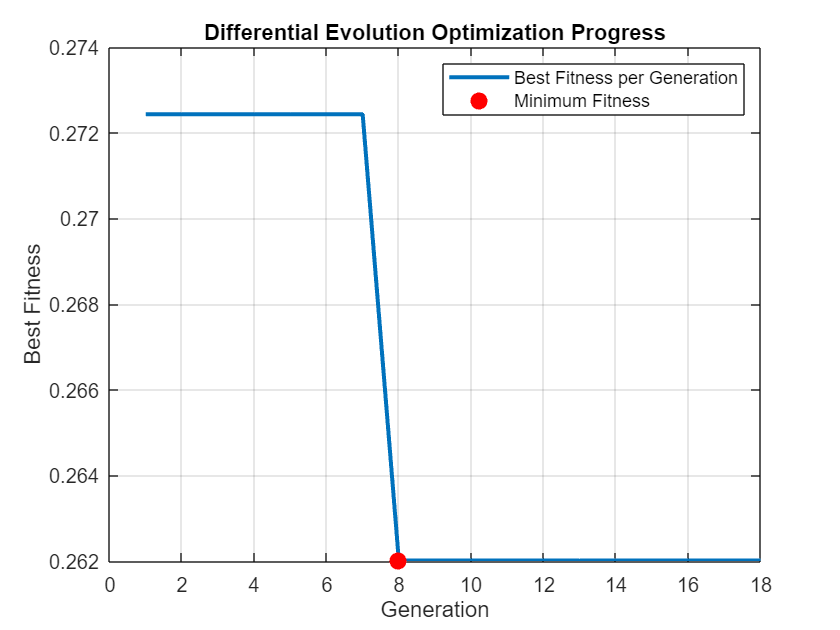


% Plot the best fitness value across generations
figure;
plot(1:gen, bestFitnessValuesDE(1:gen), 'LineWidth', 2);
hold on;

% Find the minimum fitness value and its index
[minFitnessDE, minIndexDE] = min(bestFitnessValuesDE(1:gen));

% Highlight the minimum with a red dot
plot(minIndexDE, minFitnessDE, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Add labels and title
xlabel('Generation');
ylabel('Best Fitness');
title('Differential Evolution Optimization Progress');
grid on;

% Display the minimum value in the legend
legend('Best Fitness per Generation', 'Minimum Fitness');
hold off;


% Output the best solution after the final generation
bestSolutionDE = population(minIndexDE, :);
disp(['DE Best Solution: ', num2str(bestSolutionDE)]);

DE Best Solution: 0.67212    0.064364       0.458     0.45212     0.67776


disp(['DE Best Fitness: ', num2str(minFitnessDE)]);

DE Best Fitness: 0.26201



% Objective function for DE (same as GA's)

function F = objectiveFunction(Q, observedQ, sigma, lambda, RD, RC, S, E, Fcons, alpha, beta, gamma, delta, theta, actualTimes, speeds, distances)
    % Compute penalties
    discrepancyTerm = 0;
    for i = 1:length(Q)
        % Calculate discrepancy based on delta(t_i) - (t_i * v_i) / s_i
        discrepancyTerm = discrepancyTerm + (delta - ((actualTimes(i) * speeds(i)) / distances(i)) - Q(i))^2;
    end
    discrepancyTerm = discrepancyTerm / sigma^2;
    
    % Regularization term
    regularizationTerm = lambda * norm(Q, 2)^2;
    
    % Penalties
    recklessDrivingPenalty = alpha * sum(RD);
    railroadDelayPenalty = beta * sum(RC);
    signalDelayPenalty = gamma * sum(S);
    emissionPenalty = delta * sum(E);
    fuelPenalty = theta * sum(Fcons);
    
    % Combine terms into the final objective function
    F = 1 * (discrepancyTerm + regularizationTerm + recklessDrivingPenalty ...
        + railroadDelayPenalty + signalDelayPenalty + emissionPenalty + fuelPenalty);
end
